clear

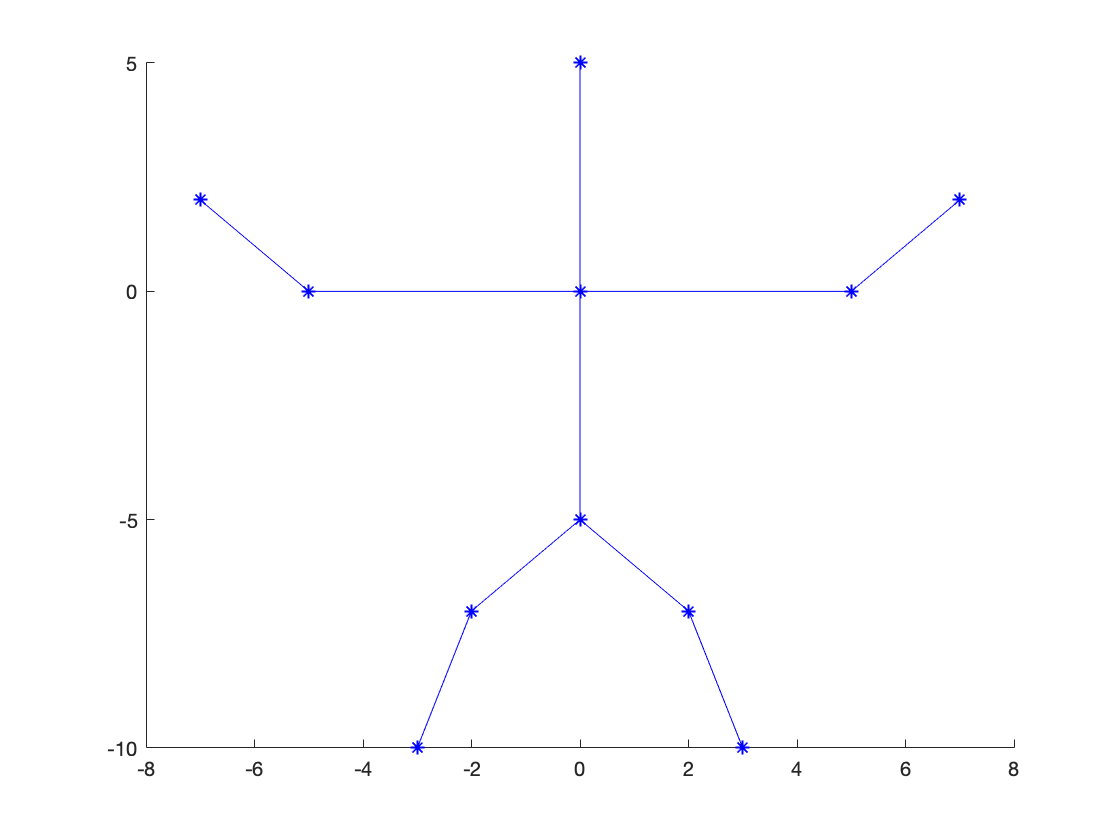

neck = [0, 0; 0, 5];
left_upper_arm = [0, -5; 0, 0];
left_forearm = [-5, -7; 0, 2];
right_upper_arm = [0, 5; 0, 0];
right_forearm = [5, 7; 0, 2];
body = [0, 0; 0, -5];
left_thigh = [0, -2; -5, -7];
left_lower_leg = [-2, -3; -7, -10];
right_thigh = [0, 2; -5, -7];
right_lower_leg = [2, 3; -7, -10];
skeleton = {neck, left_upper_arm, left_forearm, right_upper_arm, right_forearm, body, left_thigh, left_lower_leg, right_thigh, right_lower_leg};

% plot
clf
figure(1)
hold on;
for i = 1:10
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end

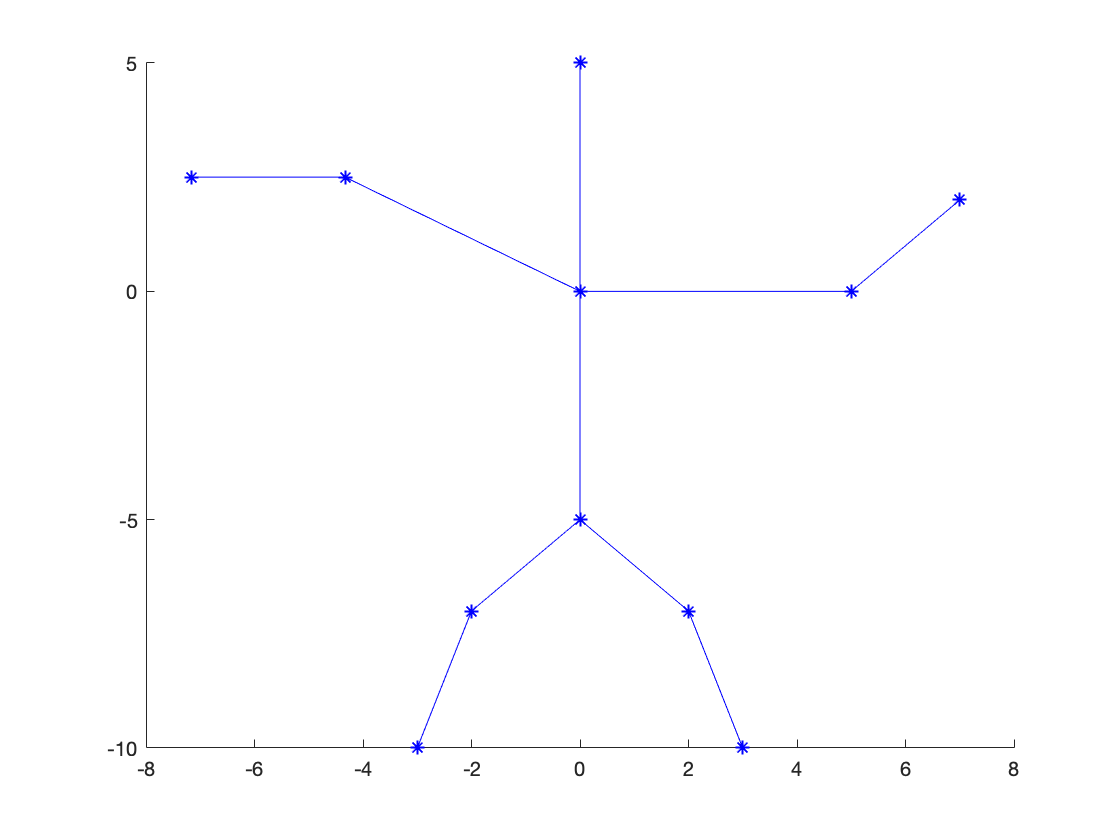

% move left_upper_arm
% rotate left_upper_arm
theta = 30;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
tmp = trans*cell2mat(skeleton(2));
dxy = tmp - cell2mat(skeleton(2));
skeleton(2) = mat2cell(tmp,2,2);
%move left_fore_arm accordingly
dxy = dxy(:,2);
skeleton(3) = mat2cell(cell2mat(skeleton(3)) + dxy,2,2);
% move and rotate left_forearm
theta = -45;
trans = [cosd(theta), sind(theta); -sind(theta), cosd(theta)];
coor = cell2mat(skeleton(3));
new_coor = coor - coor(:,1);
new_coor = trans*new_coor;
new_coor = new_coor + coor(:,1);
skeleton(3) = mat2cell(new_coor,2,2);
% plot
clf
figure(1)
hold on;
for i = 1:10
    tmp = cell2mat(skeleton(i));
    plot(tmp(1,1:end), tmp(2,1:end),'*b-')
end